load('s.mat', 's')
fs=128; %samping freq

close all

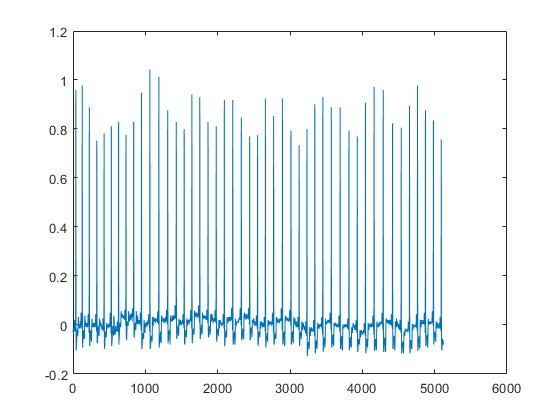

plot(s)

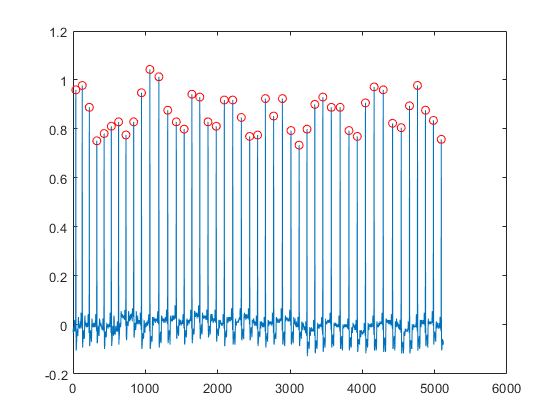

close all

%cut everything below 0.4 mV
f_For_peaks=s;
f_For_peaks(f_For_peaks<0.4)=0;
%TODO (1P): explain the preceding two lines. Why do we do that and is it necessary to do that?
%ANSWER: We remove all peaks of ampitude less than 0.4mV. The necessity of
%doing this is difficult to tell, it might help so that no "fake" peaks are
%detected, however, from the plot of s, this seems unlikely, so in this
%situation it is most likely unnecessary.

%find peaks
[pks,peak_locations]=findpeaks(f_For_peaks);

%plot the signal and the peaks
figure
plot(s)
hold on
plot(peak_locations,s(peak_locations),'ro')


t=0:1/fs:(length(s)-1)/fs; %time

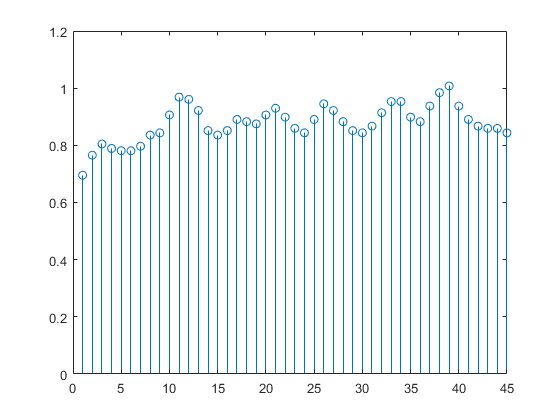

%time locations of peaks
tPL=t(peak_locations(2:end));
%tHRL=tPL(2:end);

%durations of heart beats
HBduration=diff(t(peak_locations)); %in time

figure
stem(HBduration)

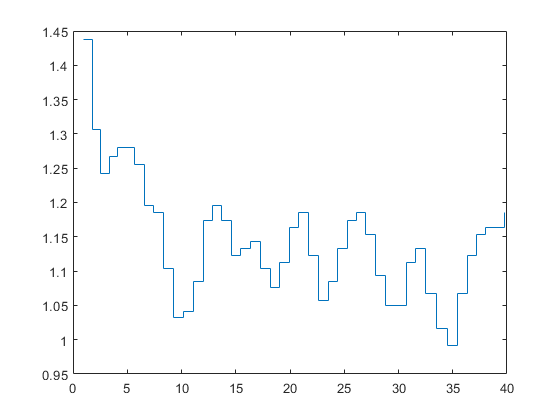


%heart rate
HR=1./HBduration;

figure
stairs(tPL,HR)

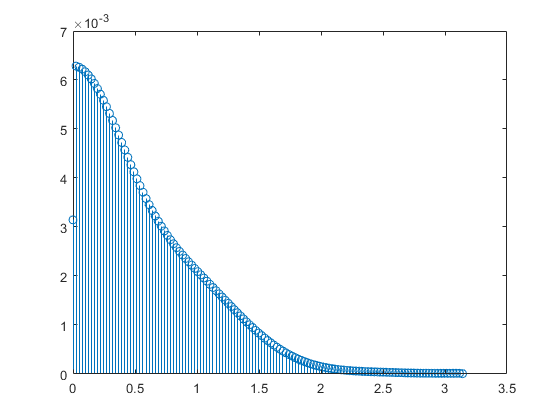

%estimate PSD
[ppx,w]=pwelch(HR - mean(HR));
figure
stem(w,ppx)

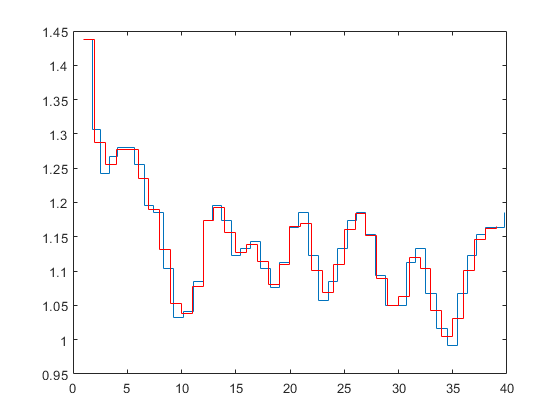


%I have to resample the HR. 
TD=tPL(end) - tPL(1); %total time
fsHR=1; %sampling frequency

%fixed time distances
TInterpolated=tPL(1):1/fsHR:tPL(end);
vq1 = interp1(tPL,HR,TInterpolated);

%TODO (1P): Why do we have to resample?
%ANSWER: We resample to get equidistance, since FT is based on equidistance
%between samples.

%before and after resampling
figure
stairs(tPL,HR)
hold on
stairs(TInterpolated,vq1,'r')

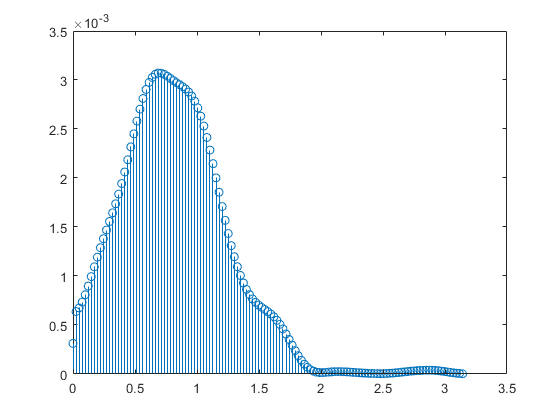


[ppx,w]=pwelch(vq1 - mean(vq1),20);
%[ppx,w]=pwelch(vq1 - mean(vq1),400);

%TODO (2P): Why do we use here pwelch and not fft?
%ANSWER: pwelch is used on finite length signals as better estimate of the
%spectrum than normal FT. We need to do pwelch since we can only do
%estimate of random signals spectrum, we can never get the true spectrum.
%Which is especially important since the heart has random variables.

%plot it now again after resamling
figure
stem(w,ppx)

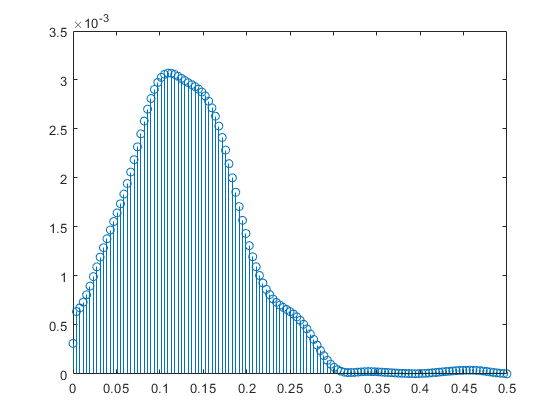


%the same plot but now with real frequencies
w1=(0:1/(length(w)-1):1)*(fsHR/2);
figure
stem(w1,ppx)


%TODO (2P): Explain why the peak in the power spectral density corresponds
%to the breathing rate.
%ANSWER: Because breathing rate is known to impact HR (known as RSA,
%respiratory sinus arrhythmia), so this should be the component that has
%the most power.

